## DGP

Adapted from Hastie & Tibshirani, p 12


$$Y = \sin(\pi X)+\epsilon$$


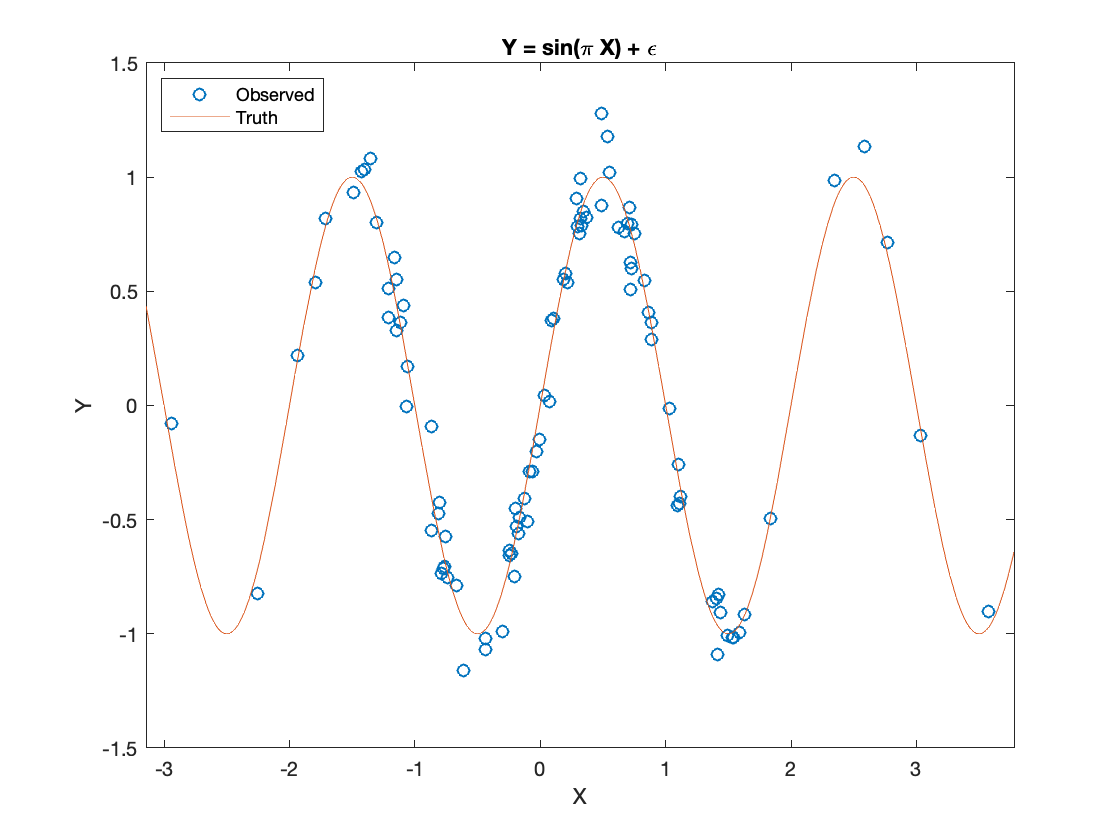

rng default; % For testing

n = 100;
k = 1;

X = normrnd(0,1,n,k);
X = sort(X);
domain = [X(1)-.2 X(end)+.2];
epsilon = normrnd(0,1/9,n,k);
Y = sin(pi*X)+epsilon;
range = [-1.2 1.2];

plot(X,Y,'o');
hold on;
fplot(@(x) sin(pi*x));
title('Y = sin(\pi X) + \epsilon');
legend('Observed', 'Truth','Location','Northwest');
xlabel('X');
ylabel('Y');
xlim(domain);
hold off;


save('dgp.mat','X','Y');